% Example of fasterRCNN model based classifier for a subset of the
% Vehile data containing only one classes.

close all;
clear all;
clc;

## Load the ground truth data

imageDir = fullfile(matlabroot,'toolbox','vision','visiondata','vehicles');
addpath(imageDir);
data = load('vehicleTrainingGroundTruth.mat');
gTruth = data.vehicleTrainingGroundTruth;

## Change file paths in the ground truth as the labelling was done on a

alternativePaths = ["/Users/s423738/Dropbox/UC/Teaching/8890_CVIA_PG/2022/Data/Wanya_East_181115_to_091215_DM_Subset" "P:\Week_11"];
unresolvedPaths = changeFilePaths(gTruth, alternativePaths);

## For the labelled ground truth data, get the image data store and bounding 

[imds,blds] = objectDetectorTrainingData(gTruth);

## Combine the two datastores

cds = combine(imds, blds);

Resize the datasets images to a reasonable size for our Faster RCNN architecture.

inputImageSize =  [224 224 3];
% preprocessedTrainingData = ...
%     transform(cds, @(data) preprocessData(data, inputImageSize));

preprocessedTrainingData = ...
    transform(cds, @(data) augmentData(data, inputImageSize));

##Display Sample input

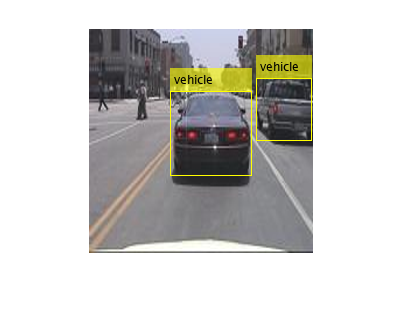

resized_data = read(preprocessedTrainingData); 
img = resized_data{1};
bboxes  = resized_data{2};
label = resized_data{3}; 
if (~isempty(bboxes))   
    img = insertObjectAnnotation(img, 'rectangle', bboxes, label);
end
% Display Ground truth and resized image
figure,imshow(img);  

## Check if we have a GPU available and clear any old data from it

disp('GPU count')

GPU count


disp(gpuDeviceCount())

     1



disp(gpuDevice(1))

  CUDADevice with properties:

                      Name: 'GRID T4-8Q'
                     Index: 1
         ComputeCapability: '7.5'
            SupportsDouble: 1
             DriverVersion: 11.4000
            ToolkitVersion: 11
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 8.5899e+09
           AvailableMemory: 6.0357e+09
       MultiprocessorCount: 40
              ClockRateKHz: 1590000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 0
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1



device = gpuDevice(1);
reset(device);  % Clear previous values that might still be on the GPU

## Set the training options

options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.0001, ...
        'MiniBatchSize', 4, ...
        'MaxEpochs', 10, ...
        'Verbose', true, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1);

## Prepare the fasterRCNN training. To keep things simple, we use

numClasses = 1;

% % We use the AlexNet architecture without pretrained weigths as the CNN
% % feature extractor.
featureExtractionNetwork = layerGraph(alexnet('Weights', 'none'));
% % or using pretrained weights from ImageNet
% featureExtractionNetwork = layerGraph(alexnet('Weights', 'imagenet'));

featureLayer = 'relu5'; 

numAnchors = 3;
anchorBoxes = estimateAnchorBoxes(preprocessedTrainingData, numAnchors);

lgraph = fasterRCNNLayers(inputImageSize,numClasses,anchorBoxes, ...
                          featureExtractionNetwork,featureLayer);

## Train the fasterRCNN object detector model

[detector, info] = ...
    trainFasterRCNNObjectDetector(preprocessedTrainingData, lgraph, options, ...
                    'FreezeBatchNormalization', false, ... 
                    'NegativeOverlapRange',[0 0.1], ...
                    'PositiveOverlapRange',[0.4 1]);            

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* vehicle

Training on single GPU.
Initializing input data normalization.
|=============================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |      Rate       |
|=============================================================================================================================================|
|       1 |           1 |       00:00:21 |       5.0585 |       76.80% |         0.45 |           58.27% |             1.70 |      1.0000e-04 |
|       1 |           2 |       00:00:23 |       2.4314 |

## Now, let's test the object detector

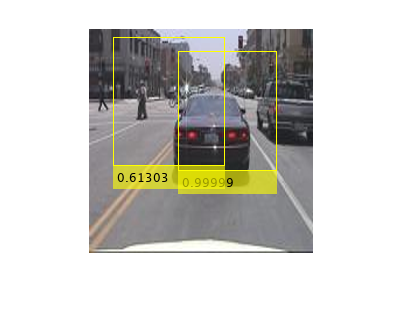

i_x = read(preprocessedTrainingData);

fname = imds.Files{1};     % Pick an image
img = imread(fname);
img = imresize(img, inputImageSize(1:2));
[bboxes, scores] = detect(detector, img);   % Detect objects

if (~isempty(bboxes))   % If any known objects found, overlay bounding box
    img = insertObjectAnnotation(img, 'rectangle', bboxes, scores);
end
figure,imshow(img);     % Display image and detected objects

## Helper function - Preprocessing the training data to fit the target

function boxes = helperSanitizeBoxes(boxes, ~)
    persistent hasInvalidBoxes
    valid = all(boxes > 0, 2);
    if any(valid)
        if ~all(valid) && isempty(hasInvalidBoxes)
            % Issue one-time warning about removing invalid boxes.
            hasInvalidBoxes = true;
            warning('Removing ground truth bouding box data with values <= 0.')
        end
        boxes = boxes(valid,:); 
    end
end
    
function data = augmentData(data, targetSize)
    scale = targetSize(1:2)./size(data{1}, [1 2]);
    data{1} = imresize(data{1}, targetSize(1:2));
    bboxes = round(data{2});
    data{2} = bboxresize(bboxes, scale); 

    tform = randomAffine2d('XReflection',true);
    rout = affineOutputView(targetSize, tform);
    data{1} = imwarp(data{1},tform,'OutputView',rout);
    data{2} = helperSanitizeBoxes(data{2}, targetSize);
    data{2} = bboxwarp(data{2}, tform, rout);
end

function data = preprocessData(data, targetSize)
scale = targetSize(1:2)./size(data{1}, [1 2]);
data{1} = imresize(data{1}, targetSize(1:2));
bboxes = round(data{2});
data{2} = bboxresize(bboxes, scale); 
end